# Face Recognition using SVD

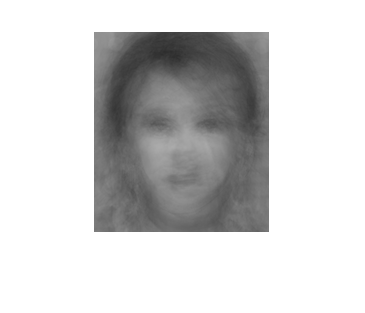

clear;clc;

N = 20;
m = 200;
n = 175;

faces = zeros(m*n,2*N);
avg = zeros(m*n,1);
count = 0;
for k=1:N
    ff = ['faces/stallone',num2str(k,'%02d'),'.jpg'];
    u = double(rgb2gray(imread(ff))); % Read the image into a matrix
    faces(:,k) = reshape(u,m*n,1);
    avg = avg + reshape(u,m*n,1);
    count = count + 1;
end

for k=1:N
    ff = ['faces/taylor',num2str(k,'%02d'),'.jpg'];
    u = double(rgb2gray(imread(ff))); % Read the image into a matrix
    faces(:,k+N) = reshape(u,m*n,1);
    avg = avg + reshape(u,m*n,1);
    count = count + 1;
end

avg = avg / count;

figure(1);
imshow(uint8(reshape(avg,[m,n])));

## PCA for facial features

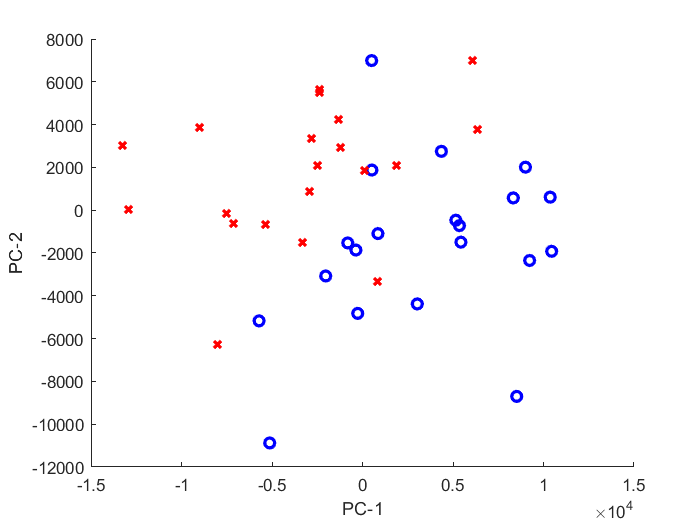

for k=1:2*N
    faces(:,k) = faces(:,k) - avg;
end

[U,S,V] = svd(faces,'econ');

figure(2), hold on;
for k=1:2*N
    x = transpose(faces(:,k))*U(:,1);
    y = transpose(faces(:,k))*U(:,2);
    z = transpose(faces(:,k))*U(:,3);
    
    if k > N
        plot3(x,y,z,'rx','LineWidth',2); % Taylor
    else
        plot3(x,y,z,'bo','LineWidth',2); % Stallone
    end
end
xlabel('PC-1');
ylabel('PC-2');
zlabel('PC-3');

## Test sample unkown image

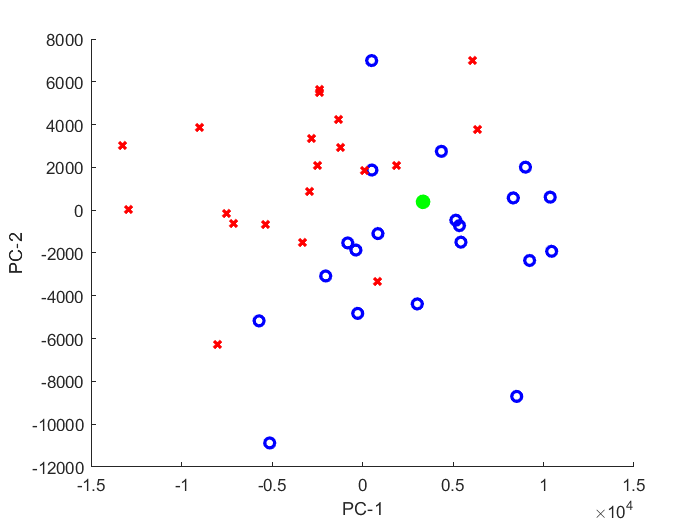

ff = ['faces/teststallone1.jpg'];
u = double(rgb2gray(imread(ff))); % Read the image into a matrix
u_dat = reshape(u,m*n,1) - avg;
x = transpose(u_dat)*U(:,1);
y = transpose(u_dat)*U(:,2);
z = transpose(u_dat)*U(:,3);
plot3(x,y,z,'g.','MarkerSize',30);